Hour 01: 427 target bins, 403 reference bins


Hour 01: 243 / 427 bins significant


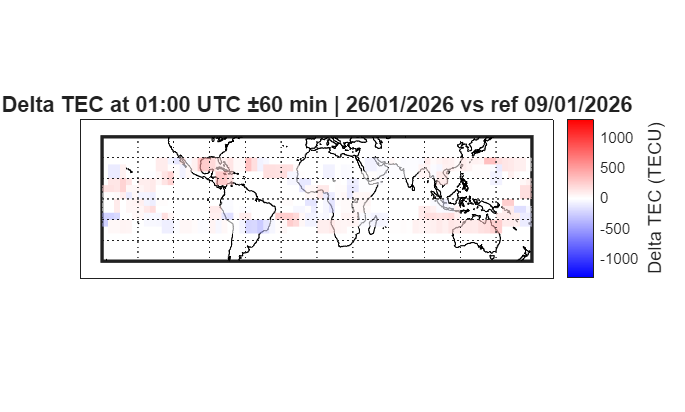

Hour 03: 417 target bins, 396 reference bins


Hour 03: 227 / 417 bins significant


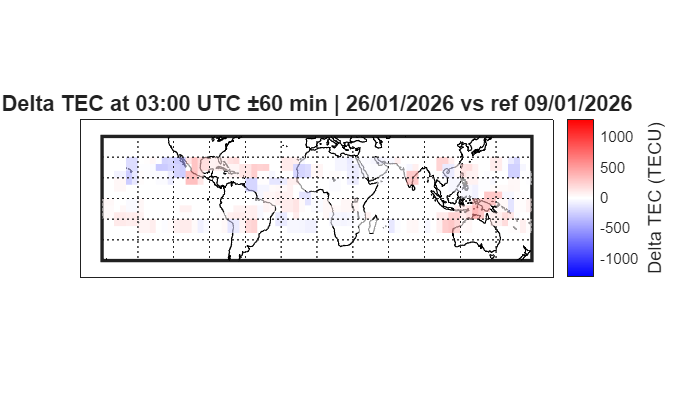

Hour 05: 417 target bins, 411 reference bins


Hour 05: 246 / 417 bins significant


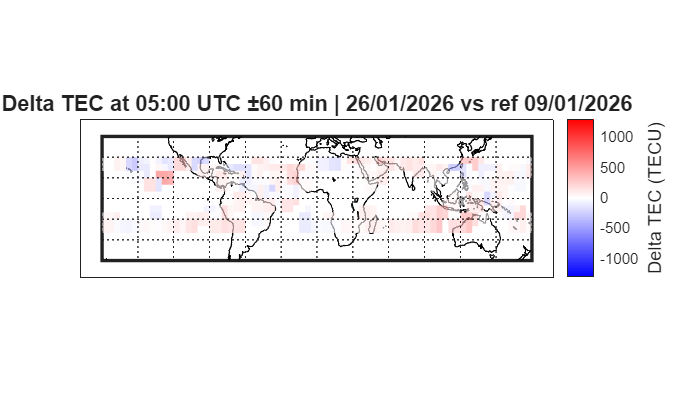

Hour 07: 416 target bins, 409 reference bins


Hour 07: 235 / 416 bins significant


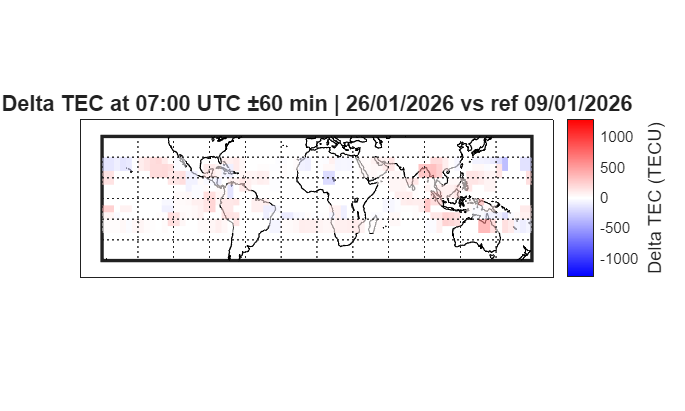

Hour 09: 425 target bins, 398 reference bins


Hour 09: 240 / 425 bins significant


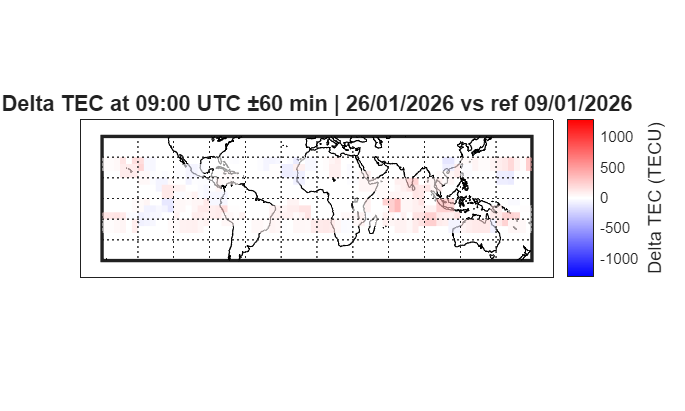

Hour 11: 419 target bins, 393 reference bins


Hour 11: 220 / 419 bins significant


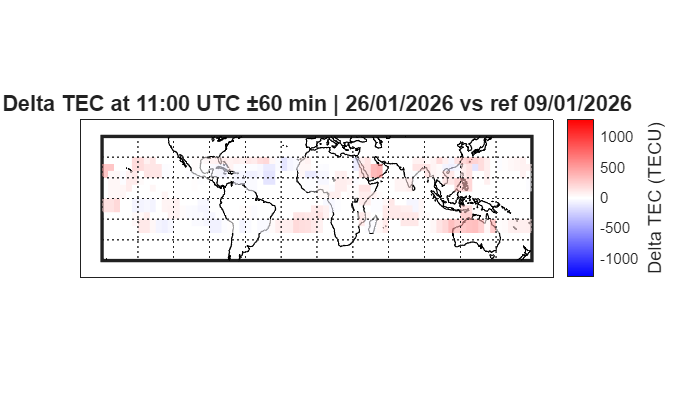

Hour 13: 413 target bins, 347 reference bins


Hour 13: 213 / 413 bins significant


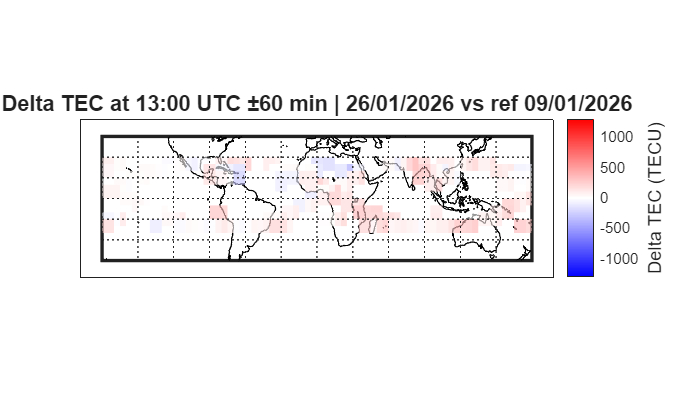

Hour 15: 413 target bins, 406 reference bins


Hour 15: 236 / 413 bins significant


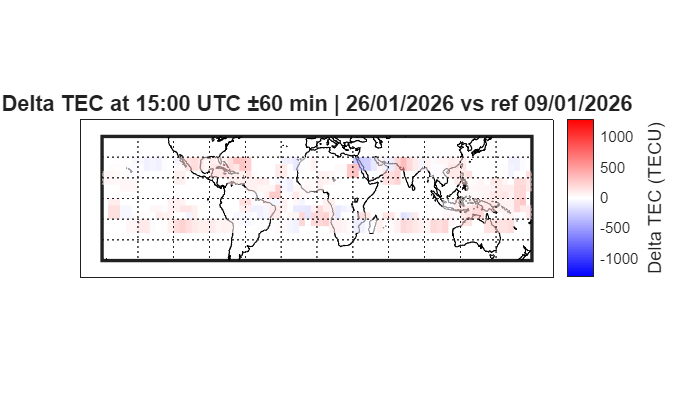

Hour 17: 421 target bins, 405 reference bins


Hour 17: 251 / 421 bins significant


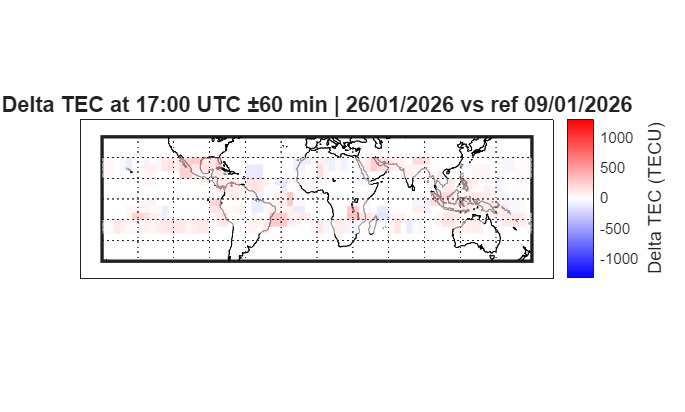

Hour 19: 414 target bins, 397 reference bins


Hour 19: 229 / 414 bins significant


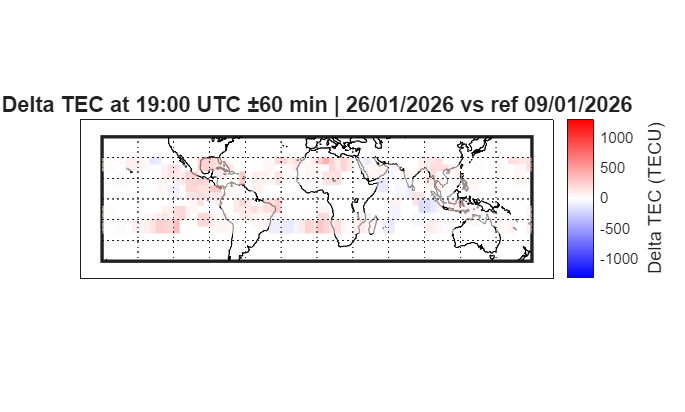

Hour 21: 416 target bins, 378 reference bins


Hour 21: 218 / 416 bins significant


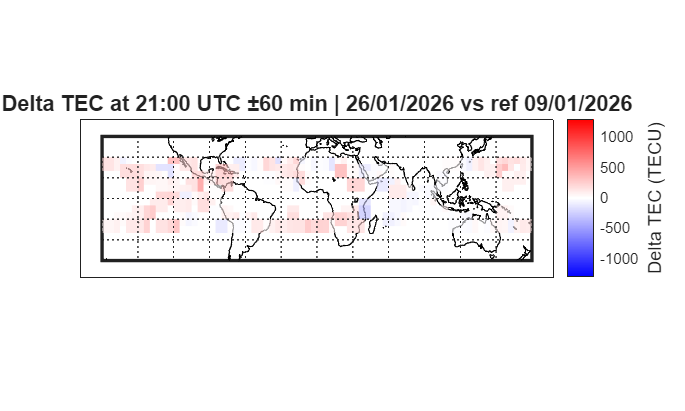

Hour 23: 414 target bins, 414 reference bins


Hour 23: 238 / 414 bins significant


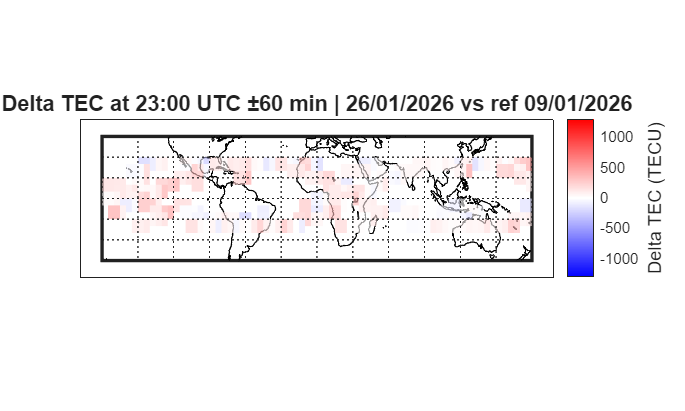

%% COSMIC delta TEC heatmap
clear min
reference_date = [COSMIC_data_reference{1}.day, COSMIC_data_reference{1}.month, year];
current_date   = [COSMIC_data{1}.day,           COSMIC_data{1}.month,           year];

%USER PARAMETERS
filter_quartiles = false;
lower_pct        = 25;
upper_pct        = 75;
bin_size         = 5; 
delta_threshold  = 0;

%% HOUR LOOP
for target_hour = 1:2:23
    target_minute  = 00;
    time_tolerance = 60;

    all_lat     = [];
    all_lon     = [];
    all_tec     = [];
    ref_all_lat = [];
    ref_all_lon = [];
    ref_all_tec = [];

    %Collect target data
    for i = 1:length(COSMIC_data)
        file_total_minutes   = COSMIC_data{i}.hour * 60 + COSMIC_data{i}.minute;
        target_total_minutes = target_hour * 60 + target_minute;
        if abs(file_total_minutes - target_total_minutes) > time_tolerance, continue; end

        elevmask = COSMIC_data{i}.elevation < 0;
        lat = COSMIC_data{i}.GEO_lat_LEO(elevmask);
        lon = COSMIC_data{i}.GEO_lon_LEO(elevmask);
        tec = COSMIC_data{i}.TEC(elevmask);

        if isempty(lat) || isempty(lon) || isempty(tec), continue; end
        if any(isnan(lat)) || any(isnan(lon)) || any(isnan(tec)), continue; end

        all_lat = [all_lat; lat];
        all_lon = [all_lon; lon];
        all_tec = [all_tec; tec];
    end

    %Collect reference data
    for i = 1:length(COSMIC_data_reference)
        file_total_minutes   = COSMIC_data_reference{i}.hour * 60 + COSMIC_data_reference{i}.minute;
        target_total_minutes = target_hour * 60 + target_minute;
        if abs(file_total_minutes - target_total_minutes) > time_tolerance, continue; end

        elevmask = COSMIC_data_reference{i}.elevation < 0;
        lat = COSMIC_data_reference{i}.GEO_lat_LEO(elevmask);
        lon = COSMIC_data_reference{i}.GEO_lon_LEO(elevmask);
        tec = COSMIC_data_reference{i}.TEC(elevmask);

        if isempty(lat) || isempty(lon) || isempty(tec), continue; end
        if any(isnan(lat)) || any(isnan(lon)) || any(isnan(tec)), continue; end

        ref_all_lat = [ref_all_lat; lat];
        ref_all_lon = [ref_all_lon; lon];
        ref_all_tec = [ref_all_tec; tec];
    end

    if isempty(all_lat) || isempty(ref_all_lat)
        warning('No points found for hour %02d.', target_hour);
        continue
    end

    %Quartile filter
    if filter_quartiles
        q_low  = prctile(all_tec, lower_pct);
        q_high = prctile(all_tec, upper_pct);
        keep   = all_tec >= q_low & all_tec <= q_high;
        all_lat = all_lat(keep);
        all_lon = all_lon(keep);
        all_tec = all_tec(keep);
        fprintf('Hour %02d: kept %d / %d points (%.0f-%.0f pctile)\n', ...
            target_hour, sum(keep), length(keep), lower_pct, upper_pct);
    end

    if isempty(all_lat)
        warning('No points remain after quartile filter for hour %02d.', target_hour);
        continue
    end

    %Bin target data
    bin_lat_idx = floor(all_lat / bin_size) * bin_size + bin_size/2;
    bin_lon_idx = floor(all_lon / bin_size) * bin_size + bin_size/2;
    valid = ~isnan(bin_lat_idx) & ~isnan(bin_lon_idx) & ...
            all_lat >= -90 & all_lat <= 90 & all_lon >= -180 & all_lon <= 180;
    [G, bin_lat, bin_lon] = findgroups(bin_lat_idx(valid), bin_lon_idx(valid));
    bin_tec = splitapply(@max, all_tec(valid), G);

    %Bin reference data
    ref_bin_lat_idx = floor(ref_all_lat / bin_size) * bin_size + bin_size/2;
    ref_bin_lon_idx = floor(ref_all_lon / bin_size) * bin_size + bin_size/2;
    ref_valid = ~isnan(ref_bin_lat_idx) & ~isnan(ref_bin_lon_idx) & ...
                ref_all_lat >= -90 & ref_all_lat <= 90 & ref_all_lon >= -180 & ref_all_lon <= 180;
    [G_ref, ref_bin_lat, ref_bin_lon] = findgroups(ref_bin_lat_idx(ref_valid), ref_bin_lon_idx(ref_valid));
    ref_bin_tec = splitapply(@max, ref_all_tec(ref_valid), G_ref);

    fprintf('Hour %02d: %d target bins, %d reference bins\n', ...
        target_hour, length(bin_tec), length(ref_bin_tec));

    %Match bins and compute delta TEC
    tol = bin_size * 0.01;
    n_bins    = length(bin_lat);
    delta_tec = nan(n_bins, 1);

    for b = 1:n_bins
        match = abs(ref_bin_lat - bin_lat(b)) < tol & ...
                abs(ref_bin_lon - bin_lon(b)) < tol;
        if any(match)
            delta_tec(b) = bin_tec(b) - ref_bin_tec(match);
        end
    end

    %Apply threshold filter
    significant = ~isnan(delta_tec) & abs(delta_tec) > delta_threshold;
    plot_lat  = bin_lat(significant);
    plot_lon  = bin_lon(significant);
    cdata     = delta_tec(significant);

    fprintf('Hour %02d: %d / %d bins significant\n', target_hour, sum(significant), n_bins);

    if isempty(plot_lat)
        fprintf('Hour %02d: nothing to plot.\n', target_hour);
        continue
    end

    %Build 2D grid nearest neighbour
    lat_vec = (-45 : bin_size : 45)';
    lon_vec = (-180 : bin_size : 180)';
    [LatGrid, LonGrid] = ndgrid(lat_vec, lon_vec);
    DeltaTECGrid = nan(size(LatGrid));

    for r = 1:size(LatGrid, 1)
        for c = 1:size(LatGrid, 2)
            distances = (plot_lat - LatGrid(r,c)).^2 + (plot_lon - LonGrid(r,c)).^2;
            [d_min, idx_min] = min(distances);
            if sqrt(d_min) <= bin_size
                DeltaTECGrid(r,c) = cdata(idx_min);
            end
        end
    end

    %Figure
    figure('Color', 'w', 'Position', [100 100 1000 600]);

    axesm('eqdcylin', ...
          'MapLatLimit', [-45  45], ...
          'MapLonLimit', [-180 180], ...
          'Frame', 'on', 'Grid', 'on')

    load coastlines
    geoshow(coastlat, coastlon, 'Color', 'k', 'LineWidth', 0.8)
    hold on

    % Heatmap via pcolorm
    h = pcolorm(LatGrid, LonGrid, DeltaTECGrid);
    set(h, 'FaceAlpha', 0.6) 

    % Diverging red-white-blue colormap
    n = 256;
    r_ch = [linspace(1,1,n/2), linspace(1,0,n/2)]';
    g_ch = [linspace(0,1,n/2), linspace(1,0,n/2)]';
    b_ch = [linspace(0,1,n/2), linspace(1,1,n/2)]';
    colormap(flipud([r_ch g_ch b_ch]))

    clim([-1300, 1300])
    cb = colorbar;
    cb.Label.String   = 'Delta TEC (TECU)';
    cb.Label.FontSize = 11;

    title(sprintf('Delta TEC at %02d:%02d UTC ±%d min | %02d/%02d/%04d vs ref %02d/%02d/%04d', ...
        target_hour, target_minute, time_tolerance, ...
        current_date(1),   current_date(2),   current_date(3), ...
        reference_date(1), reference_date(2), reference_date(3)), ...
        'FontSize', 13, 'FontWeight', 'bold')

    hold off
end